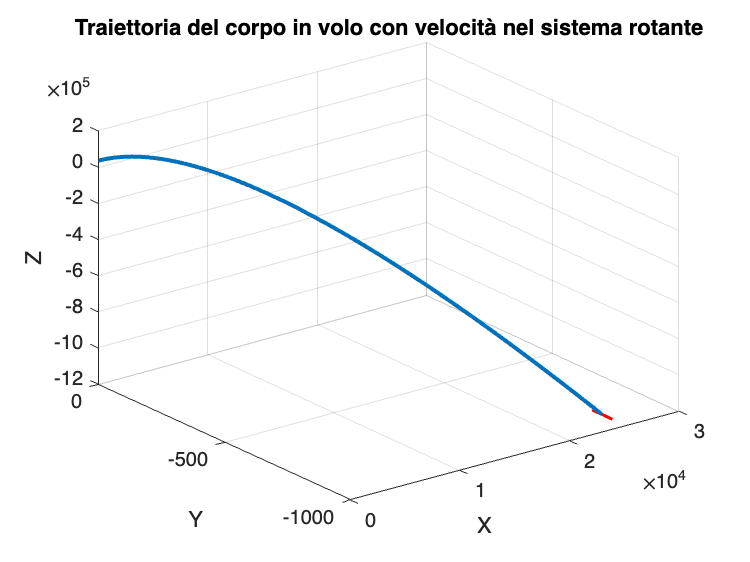

% Parametri del corpo in volo
m = 1;  % massa del glider kg
g = 9.81;  % accelerazione dovuta alla gravità in m/s^2

% Parametri del sistema rotante (Terra)
Omega = 7.2921e-5;  % velocità angolare della Terra in rad/s

% Funzione del sistema di equazioni differenziali
ode = @(t, y) [
    y(4);  % dx/dt = vx
    y(5);  % dy/dt = vy
    y(6);  % dz/dt = vz
    2 * Omega * y(5) + Omega^2 * y(1);  % d(vx)/dt = F_Coriolis_x + F_centrifuga_x
    -2 * Omega * y(4) + Omega^2 * y(2);  % d(vy)/dt = F_Coriolis_y + F_centrifuga_y
    -g + Omega^2 * y(3)  % d(vz)/dt = F_Coriolis_z + F_centrifuga_z - g
];

% Condizioni iniziali (posizione e velocità iniziali)
y0 = [0; 0; 35000; 50; 0; 0];

% Intervallo temporale
tspan = [0 500];

% Risoluzione dell'equazione differenziale
options = odeset('RelTol', 1e-6, 'AbsTol', 1e-6);
[t, y] = ode45(ode, tspan, y0, options);

% Preallocazione della matrice per la velocità
velocita = zeros(length(t), 1);

% Plot iniziale della traiettoria
figure;
h_traj = plot3(y(1, 1), y(1, 2), y(1, 3), 'LineWidth', 2);
hold on;
h_quiver = quiver3(y(1, 1), y(1, 2), y(1, 3), y(1, 4), y(1, 5), y(1, 6), 0.5, 'r', 'LineWidth', 1.5);
hold off;

xlabel('X');
ylabel('Y');
zlabel('Z');
title('Traiettoria del corpo in volo con velocità nel sistema rotante');
grid on;

% Loop per l'animazione
for i = 2:length(t)
    % Aggiorna la posizione della traiettoria
    set(h_traj, 'XData', y(1:i, 1), 'YData', y(1:i, 2), 'ZData', y(1:i, 3));

    % Aggiorna la velocità
    set(h_quiver, 'XData', y(i, 1), 'YData', y(i, 2), 'ZData', y(i, 3), ...
                  'UData', y(i, 4), 'VData', y(i, 5), 'WData', y(i, 6));

    % Aggiorna il grafico
    drawnow;

    % Pausa per controllare la velocità dell'animazione
    pause(0.05);
end